# Sprawozdanie Układy Równiań

Tomasz Kowalski 313565

clc
clear
close all


_____________________________________________________________________________

#### Rozwiązywanie układu równań metodą Eliminacj Gausa dla różnej ilości zmiennych.

n = [4 20 50 100 120];

for N = n
    disp("-------")
    N
    condNumber = 200;

    Q = orth(rand(N));
    S = diag(logspace(0, log10(condNumber), N));
    P = orth(rand(N));
    A = Q * S * P';

    X = zeros(1,N);
    Y = linspace(1, N, N);

    for i = 1 : N
        A = eliminacion(A,i);
    end

    for i = N:-1:1
        X(i)=oblicz_xi(A,X,Y,i);
    end
    
    b=A*X';
    b=Y'- b;
    b = b.^2;
    err = sqrt(sum(b))

end

-------


N = 4

err = 0

-------


N = 20

err = 4.4424e-13

-------


N = 50

err = 7.0820e-11

-------


N = 100

err = 6.8651e-09

-------


N = 120

err = 3.1394e-09

#### ____________________________________________________________________________

#### Rozwiązywanie układu równań metodą rozkładu macierzy LU dla różnej ilości zmiennych.

n = [4 20 50 100 120];

for N = n
    disp("-------")
    N
    condNumber = 200;

    Q = orth(rand(N));
    S = diag(logspace(0, log10(condNumber), N));
    P = orth(rand(N));
    A = Q * S * P';

    X = zeros(1,N);
    Y = linspace(1, N, N);

    X = rozwLU(A,Y,"G");
    b=A*X';
    b=Y'- b;
    b = b.^2;
    err = sqrt(sum(b))

    X = rozwLU(A,Y,"C");
    b=A*X';
    b=Y'- b;
    b = b.^2;
    err = sqrt(sum(b))

    X = rozwLU(A,Y,"D");
    b=A*X';
    b=Y'- b;
    b = b.^2;
    err = sqrt(sum(b))

end

-------


N = 4

err = 0

err = 2.9511e-14

err = 7.1054e-15

-------


N = 20

err = 4.6319e-12

err = 2.6587e-12

err = 4.7872e-12

-------


N = 50

err = 6.5403e-11

err = 7.5693e-11

err = 8.3798e-11

-------


N = 100

err = 1.8875e-08

err = 2.1802e-08

err = 2.2767e-08

-------


N = 120

err = 6.1808e-10

err = 5.6701e-10

err = 5.9989e-10

#### _________________________________________________________________________________________________________________

#### Rozwiązywanie układu równań metodą iteracujną dla różnej ilości zmiennych i trzech różnch metod: Jacobiego, Gausa - Seidla, SOR

n = [4 20 50 100 120];

for N = n
    disp("-------")
    N
    A = rand(N);
    D = diag(sum(abs(A), 2));
    A = A + D;

    Y = linspace(1, N, N);

    [X, err, i] = iteration(A,Y,"J");
    err
    i
    [X, err, i] = iteration(A,Y,"G");
    err
    i
    [X, err, i] = iteration(A,Y,"S");
    err
    i
end

-------


N = 4

err = 9.9209e-13

i = 84

err = 4.1267e-13

i = 18

err = 2.7752e-13

i = 20

-------


N = 20

err = 9.6945e-13

i = 306

err = 2.8663e-13

i = 19

err = 2.5370e-13

i = 24

-------


N = 50

err = 9.8074e-13

i = 836

err = 6.8147e-13

i = 20

err = 3.7685e-13

i = 26

-------


N = 100

err = 9.9375e-13

i = 1636

err = 2.4063e-13

i = 21

err = 6.1901e-13

i = 26

-------


N = 120

err = 9.9982e-13

i = 1824

err = 4.1441e-13

i = 21

err = 3.2232e-13

i = 27

#### ______________________________________________________________________________________________________

#### Porównanie czasu rozwiazywania układów równań dla powyżej zaimplementowanych metod i zestawienie ich ze soobą.

n = [5 10 20 50 100 200 500 1000 1500];
wyniki = zeros(7,length(n));
a=0;
for N = n
    a=a+1;
    disp("-------")
    N
    A = rand(N);
    D = diag(sum(abs(A), 2));
    A = A + D;
    Y = linspace(1, N, N);

    % Eliminacja Gausa 
    disp("Eliminacja Gausa")
    X = zeros(1,N);
    tic
    for i = 1 : N
        A = eliminacion(A,i);
    end

    for i = N:-1:1
        X(i)=oblicz_xi(A,X,Y,i);
    end 
    wyniki(1,a) = toc;
    wyniki(1,a)
    %

    % LU Gausa
    disp("LU Gausa")
    X = zeros(1,N);
    tic
    X = rozwLU(A,Y,"G");
    wyniki(2,a) = toc;
    wyniki(2,a)
    % 

    % LU Crouta
    disp("LU Crouta")
    X = zeros(1,N);
    tic
    X = rozwLU(A,Y,"C");
    wyniki(3,a) = toc;
    wyniki(3,a)
    % 

    % LU Dolitla
    disp("LU Dolitla")
    X = zeros(1,N);
    tic
    X = rozwLU(A,Y,"D");
    wyniki(4,a) = toc;
    wyniki(4,a)
    %

    % Iteracyujna Jaccobiego
    disp("Iteracyujna Jaccobiego")
    tic
    [X, err, i] = iteration(A,Y,"J");
    wyniki(5,a) = toc;
    wyniki(5,a)
    % 

    % Iteracyujna Gausa - Seilda
    disp("Iteracyujna Gausa - Seilda")
    tic
    [X, err, i] = iteration(A,Y,"G");
    wyniki(6,a) = toc;
    wyniki(6,a)
    %

    % Iteracyujna SOR
    disp("Iteracyujna SOR")
    tic
    [X, err, i] = iteration(A,Y,"S");
    wyniki(7,a) = toc;
    wyniki(7,a)
    %

end

-------


N = 5

Eliminacja Gausa


ans = 9.6200e-04

LU Gausa


ans = 2.2200e-04

LU Crouta


ans = 2.2500e-04

LU Dolitla


ans = 1.6300e-04

Iteracyujna Jaccobiego


ans = 2.0900e-04

Iteracyujna Gausa - Seilda


ans = 1.5000e-04

Iteracyujna SOR


ans = 1.3500e-04

-------


N = 10

Eliminacja Gausa


ans = 1.3800e-04

LU Gausa


ans = 2.3800e-04

LU Crouta


ans = 2.2800e-04

LU Dolitla


ans = 2.2200e-04

Iteracyujna Jaccobiego


ans = 1.1300e-04

Iteracyujna Gausa - Seilda


ans = 1.2100e-04

Iteracyujna SOR


ans = 1.1700e-04

-------


N = 20

Eliminacja Gausa


ans = 3.7200e-04

LU Gausa


ans = 6.5000e-04

LU Crouta


ans = 6.0700e-04

LU Dolitla


ans = 6.3100e-04

Iteracyujna Jaccobiego


ans = 1.2100e-04

Iteracyujna Gausa - Seilda


ans = 1.3100e-04

Iteracyujna SOR


ans = 1.6800e-04

-------


N = 50

Eliminacja Gausa


ans = 0.0022

LU Gausa


ans = 0.0041

LU Crouta


ans = 0.0034

LU Dolitla


ans = 0.0033

Iteracyujna Jaccobiego


ans = 1.9400e-04

Iteracyujna Gausa - Seilda


ans = 2.3300e-04

Iteracyujna SOR


ans = 3.4400e-04

-------


N = 100

Eliminacja Gausa


ans = 0.0077

LU Gausa


ans = 0.0125

LU Crouta


ans = 0.0138

LU Dolitla


ans = 0.0138

Iteracyujna Jaccobiego


ans = 6.0000e-04

Iteracyujna Gausa - Seilda


ans = 7.1200e-04

Iteracyujna SOR


ans = 5.9700e-04

-------


N = 200

Eliminacja Gausa


ans = 0.0318

LU Gausa


ans = 0.0516

LU Crouta


ans = 0.0515

LU Dolitla


ans = 0.0509

Iteracyujna Jaccobiego


ans = 7.4200e-04

Iteracyujna Gausa - Seilda


ans = 0.0018

Iteracyujna SOR


ans = 0.0013

-------


N = 500

Eliminacja Gausa


ans = 0.3571

LU Gausa


ans = 0.4529

LU Crouta


ans = 0.4840

LU Dolitla


ans = 0.4527

Iteracyujna Jaccobiego


ans = 0.0037

Iteracyujna Gausa - Seilda


ans = 0.0078

Iteracyujna SOR


ans = 0.0047

-------


N = 1000

Eliminacja Gausa


ans = 2.6337

LU Gausa


ans = 2.9150

LU Crouta


ans = 2.7356

LU Dolitla


ans = 2.6900

Iteracyujna Jaccobiego


ans = 0.0150

Iteracyujna Gausa - Seilda


ans = 0.0320

Iteracyujna SOR


ans = 0.0239

-------


N = 1500

Eliminacja Gausa


ans = 19.8861

LU Gausa


ans = 19.4651

LU Crouta


ans = 8.6533

LU Dolitla


ans = 8.5356

Iteracyujna Jaccobiego


ans = 0.0381

Iteracyujna Gausa - Seilda


ans = 0.0968

Iteracyujna SOR


ans = 0.0719

disp(n)

           5          10          20          50         100         200         500        1000        1500



disp(wyniki)

    0.0010    0.0001    0.0004    0.0022    0.0077    0.0318    0.3571    2.6337   19.8861
    0.0002    0.0002    0.0006    0.0041    0.0125    0.0516    0.4529    2.9150   19.4651
    0.0002    0.0002    0.0006    0.0034    0.0138    0.0515    0.4840    2.7356    8.6533
    0.0002    0.0002    0.0006    0.0033    0.0138    0.0509    0.4527    2.6900    8.5356
    0.0002    0.0001    0.0001    0.0002    0.0006    0.0007    0.0037    0.0150    0.0381
    0.0001    0.0001    0.0001    0.0002    0.0007    0.0018    0.0078    0.0320    0.0968
    0.0001    0.0001    0.0002    0.0003    0.0006    0.0013    0.0047    0.0239    0.0719



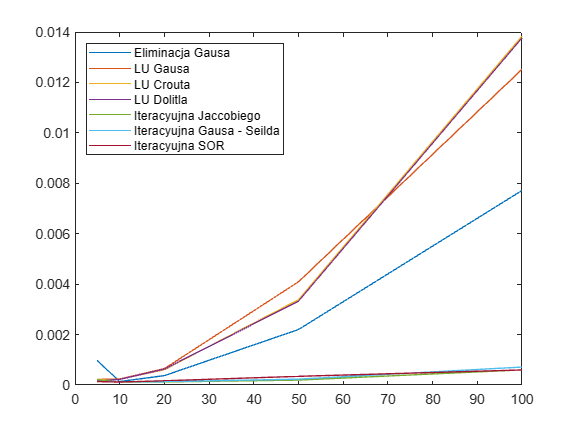

figure;

plot(n(1:5),wyniki(1,1:5)); hold on;
plot(n(1:5),wyniki(2,1:5));
plot(n(1:5),wyniki(3,1:5));
plot(n(1:5),wyniki(4,1:5));
plot(n(1:5),wyniki(5,1:5));
plot(n(1:5),wyniki(6,1:5));
plot(n(1:5),wyniki(7,1:5));
legend('Eliminacja Gausa', 'LU Gausa', 'LU Crouta', 'LU Dolitla', 'Iteracyujna Jaccobiego', 'Iteracyujna Gausa - Seilda', 'Iteracyujna SOR', 'Location', 'northwest');

**Dla lepszej widoczności prezentowane są wyniki pomiaru czasu w zależności od długości macierzy (5-100)**

- **Algorytmy Iteracyjne są zdecydowanie szybsze od pozostałych. Tam raz wykonujemy liczenie następnie w kolejnych iteracja wykonujemy tylko proste mnożenie macierzowe.**

- **ALgorytm eliminacji Gausa jest szbszy od algorytmów LU ponieważ w nim obliczamy tylko raz wymniki dla macierzy jednostkowej.**

- **Natomiast w metodach LU liczymy dwa razy wynik macieży jednostkowej.**

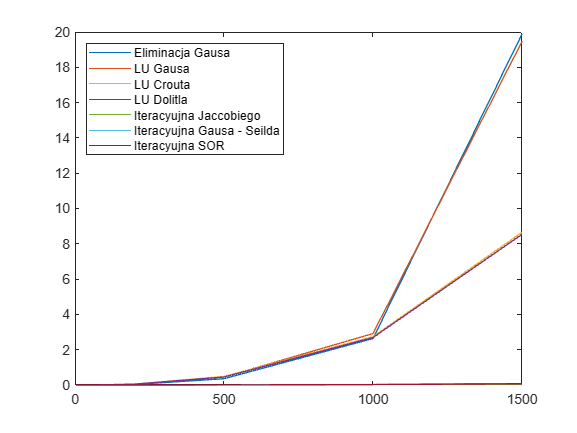

figure;

plot(n,wyniki(1,:)); hold on;
plot(n,wyniki(2,:));
plot(n,wyniki(3,:));
plot(n,wyniki(4,:));
plot(n,wyniki(5,:));
plot(n,wyniki(6,:));
plot(n,wyniki(7,:));
legend('Eliminacja Gausa', 'LU Gausa', 'LU Crouta', 'LU Dolitla', 'Iteracyujna Jaccobiego', 'Iteracyujna Gausa - Seilda', 'Iteracyujna SOR', 'Location', 'northwest');

**Możemy zauważć że motody Gausa są wolnijsze od pozostałych LU przy dużych macierzach bo sama eliminacja trwa długo. Jednak są nieporównywalnie wolniejsze od algorytmów iteracyjnych**

Funkcje wykożystane do eliminacji Gausa.

function result = eliminacion (A,i)
    n = length(A);

    for j = i+1 : n
    tmp = A(j, i)/A(i, i);
    elemV = tmp*A(i,:);
    A(j,:) = A(j,:)-elemV;  
    end

    result = A;
end



function result = oblicz_xi (A, X, Y, i)
    n = length(A);
    for j = i-1 : n-1
        tmp1 = X(n-j:n).*A(i,n-j:n) ;
        tmp = sum(tmp1);
        tmp = Y(i) - tmp;
        tmp = tmp/A(i,i);
    end
    result = tmp;
end

Funkcje wykożystane do rozkładu LU

function X = rozwLU(A,Y,metoda)
    switch metoda
        case "G"
            [L,U]=luGauss(A);
        case "C"
            [L,U]=luCrouta(A);
        case "D"
            [L,U]=luDoolittle(A);
    end

    Z = oblicz_z(L,Y);
    X = oblicz_x(U,Z);
end

function [L1, U1] = luCrouta(A)
    n = length(A);
    L = zeros(n,n);
    U = zeros(n,n);
    for i = 1 : n
        for k = i : n
            sum = 0;
            for j = 1 : i
                sum = sum + (L(k,j) * U(j,i));
            end
            L(k,i) = A(k,i) - sum;
        end

        for k = i : n
            if (i == k)
                U(i,i) = 1;
            else
                sum = 0;
                for j = 1 : i
                    sum = sum + (L(i,j) * U(j,k));
                end
                U(i,k) = (A(i,k) - sum)/L(i,i);
            end
        end
    end
    L1 = L;
    U1 = U;
end

function [L1, U1] = luDoolittle(A)
    n = length(A);
    L = zeros(n,n);
    U = zeros(n,n);
    for i = 1 : n
        for k = i :n
            sum = 0;
            for j = 1 : i
                sum = sum + (L(i,j) * U(j,k));
            end
            U(i,k) = A(i,k) - sum;
        end

        for k = i : n
            if (i == k)
                L(i,i) = 1;
            else
                sum = 0;
                for j = 1 : i
                    sum = sum + (L(k,j) * U(j,i));
                end
                L(k,i) = (A(k,i) - sum)/U(i,i);
            end
        end
    end
    L1 = L;
    U1 = U;
end

function [L, U] = luGauss(A)
    n = length(A);
    L = eye(n);
    U = A;
    for i = 1 : n
        [L, U] = eliminacionGauss(L,U,i);
    end
end


function [L1, U1] = eliminacionGauss (L,U,i)
    n = length(U);

    for j = i+1 : n
    tmp = U(j, i)/U(i, i);
    L(j,i) = tmp;
    elemV = tmp*U(i,:);
    U(j,:) = U(j,:)-elemV;  
    end
    
    L1 = L;
    U1 = U;
end

function Z1 = oblicz_z(L,Y)
    n = length(L);
    Z = zeros(1,n);
    for i = 1 : n
        Z(i) = oblicz_zi(L,Z,Y,i);
    end
    Z1 = Z;
end

function result = oblicz_zi (L,Z,Y,i)
    for j = 1 : i
        tmp = Z(1:i-1).*L(i,1:i-1);
        tmp = sum(tmp);
        tmp = Y(i) - tmp;
        tmp = tmp/L(i,i);
    end
    result = tmp;
end

function X1 = oblicz_x (U,Z)
    n = length(U);
    X = zeros(1,n);
    for i = n:-1:1
        X(i)=oblicz_xi1(U,X,Z,i);
    end
    X1 = X;
end

function result = oblicz_xi1 (U, X, Z, i)
    n = length(U);
    for j = i-1 : n-1
        tmp = X(n-j:n).*U(i,n-j:n) ;
        tmp = sum(tmp);
        tmp = Z(i) - tmp;
        tmp = tmp/U(i,i);
    end
    result = tmp;
end

**Funkcje wykozystane do metod Iteracyjnych**

function [X, err, i] = iteration (A,Y,metoda)
    n= length(A);
    err = inf;
    switch metoda
        case "J"
            [M,W] = jacobi (A,Y);
        case "G"
            [M,W] = GaSe(A,Y);
        case "S"
            [M,W] = SOR(A,Y);
    end
    X = zeros(1,n);
    %inicjalizacja x
    for i = 1 : length(A)
        X(i) = 1;
    end
    
    i=0;
    while err > 10^(-12)
        [X, err] = obliczIter(A,X,Y,M,W);
        i = i+1;   
    end
    err;
    i;
end

function [X1, err1] = obliczIter (A,X,Y,M,W)
    Xn = (M * X')' + W;
    b = (Y' - (A * Xn')).^2;
    x = X.^2;
    xe = sqrt(sum(x));
    be = sqrt(sum(b));
    err1 = be/xe;
    X1 = Xn;
end

function [M,W] = jacobi (A,Y)
    n = length(A);
    D = zeros(n,n);
    M = zeros(n,n);
    W = zeros(1,n);
    for i = 1 : n
        D(i,i) = A(i,i);
    end
    M = -(A - D); % -(L+U)
    D = inv(D);
    M = D * M;
    for i = 1 : n
        W(i) = Y(i) * D(i,i);
    end
end

function [M,W] = GaSe (A,Y)
    n = length(A);
    M = zeros(n,n);
    W = zeros(1,n);
    [L,D,U] = ldu(A);
    M = -inv(D+L) * U;
    W = (inv(D+L) * Y')'; 
end

function [M,W] = SOR (A,Y)
    n = length(A);
    omg = 1.1;
    M = zeros(n,n);
    W = zeros(1,n);
    [L,D,U] = ldu(A);
    M = (D+omg*L)\((1-omg)*D-omg*U);
    W = ((D+omg*L)\(omg*Y'))';
end

function [L,D,U] = ldu(A)
    n = length(A);
    L = zeros(n,n);
    D = zeros(n,n);
    U = zeros(n,n);

    for i = 1 :n
        for j = 1 :n
            if (i == j)
                D(i,i) = A(i,i);
            elseif (i<j)
                U(i,j) = A(i,j);
            elseif (i>j)
                L(i,j) = A(i,j);
            end

        end
    end

end